clear All; close all; 
format short;

img = imread("test14.png");
[binary_img, centroids] = segment_blue_markers(img);


% Get props' centroids
stats = regionprops("table",binary_img,"Centroid","Area","Circularity");
% Store data
centroids = cat(1,stats.Centroid);
areas = cat(1,stats.Area);
circularity = cat(1,stats.Circularity);

% Largest circle
largestArea = max(areas);
i = find(areas == largestArea); % coordinates of the Largest circle

% Clone variable
centroidsNew = centroids;
% Remove the largest circle
centroidsNew(i,:) = [];

% 3rd column: Calculate and add distanceFromLargest circle
distanceFromLargest = [centroidsNew, sqrt(abs(centroidsNew(:,1)-centroids(i,1)).^2 + abs(centroidsNew(:,2)-centroids(i,2)).^2)];
% 4th column: Sum of coordinates
distanceFromLargest = [distanceFromLargest, distanceFromLargest(:,1)+distanceFromLargest(:,2)]

distanceFromLargest = 	1.0e+03 *

    0.0975    0.3363    0.6089    0.4338
    0.2274    0.6061    0.3094    0.8335
    0.3560    0.2116    0.6735    0.5676
    0.4875    0.4745    0.4294    0.9620
    0.6051    0.0914    0.8302    0.6966
    0.6230    0.7456    0.2966    1.3687
    0.7380    0.3477    0.6562    1.0857
    0.8748    0.6118    0.5817    1.4867


% Sort in the ascending order of distanceFromLargest
distanceSorted = sortrows( distanceFromLargest, 3)

distanceSorted = 	1.0e+03 *

    0.6230    0.7456    0.2966    1.3687
    0.2274    0.6061    0.3094    0.8335
    0.4875    0.4745    0.4294    0.9620
    0.8748    0.6118    0.5817    1.4867
    0.0975    0.3363    0.6089    0.4338
    0.7380    0.3477    0.6562    1.0857
    0.3560    0.2116    0.6735    0.5676
    0.6051    0.0914    0.8302    0.6966


sorted3 = sortrows( distanceSorted(1:3,:), 4)

sorted3 = 	1.0e+03 *

    0.2274    0.6061    0.3094    0.8335
    0.4875    0.4745    0.4294    0.9620
    0.6230    0.7456    0.2966    1.3687


sorted5 = sortrows( distanceSorted(4:8,:), 4)

sorted5 = 	1.0e+03 *

    0.0975    0.3363    0.6089    0.4338
    0.3560    0.2116    0.6735    0.5676
    0.6051    0.0914    0.8302    0.6966
    0.7380    0.3477    0.6562    1.0857
    0.8748    0.6118    0.5817    1.4867



% Now put them in P, order is right as required
P = [centroids(i,1:2)' sorted3(:,1:2)' sorted5(:,1:2)' ; ones(1,9) ]

P =   361.2599  227.3712  487.4661  623.0346   97.5110  356.0000  605.1291  738.0084  874.8250
  885.0262  606.1361  474.5396  745.6325  336.2582  211.5810   91.4269  347.7044  611.8315
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Q = [ 0 0 250 250 0 250 500 500 500; 0 250 250 0 500 500 500 250 0; ones(1,9) ];

H = simple_homography(P,Q)

H =     0.7877   -0.3788   50.5531
   -0.3947   -0.7421  799.3211
   -0.0000    0.0001    1.0000


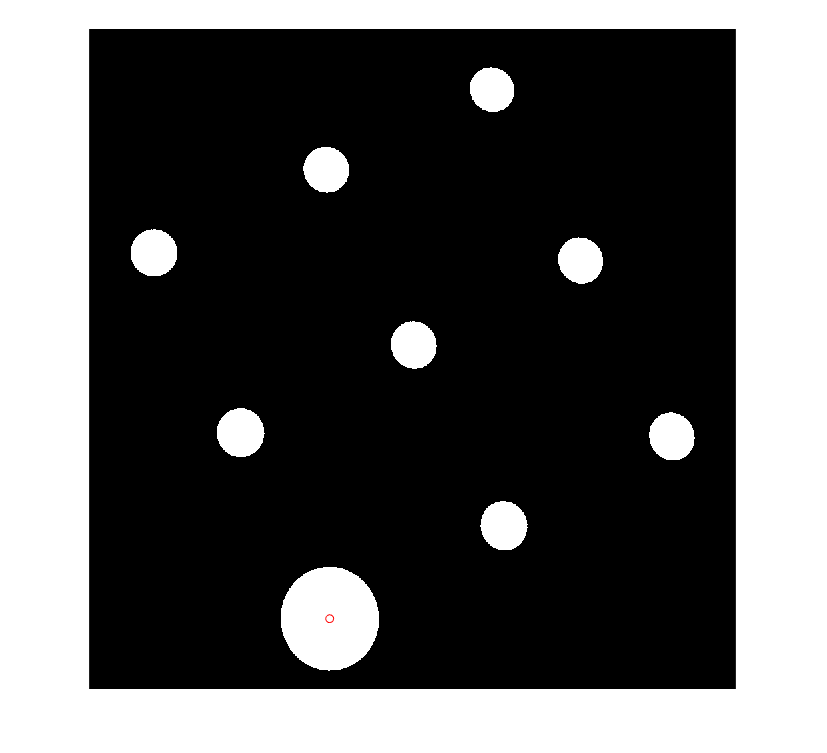






figure();
imshow(binary_img);
hold on;
plot(centroids(i,1), centroids(i,2), 'ro');